## 1. Power Converter Loss

### 1) Jansson Thesis

IGBT or SIC

% Define given variables
Vt_IGBT = 0.695;      % V
Vt_diode = 0.797;     % V
Kv_IGBT = 1.35;      
Kv_diode = 0.6;
f_sw = 10000; % Hz
V_DC = ; % DC-voltage, fill in your value
I_em_rms = ; % EM current rating in A (rms), fill in your value
hat_is = ; % Amplitude of the phase current, fill in your value
theta = ; % Phase angle in radians, fill in your value
m1 = ; % Fundamental modulation index, fill in your value


#### Calculate derived variables


I_cn = 1.092 * I_em_rms - 6.05;
Ron_IGBT = 990.07 * I_cn^(-1.003); % mOhm
Ron_diode = 675.61 * I_cn^(-1.004); % mOhm
E_onIGBT = 9.964e-6 * hat_is^2 + 0.0156 * hat_is + 0.6221; % mJ
E_offIGBT = 2.4259e-8 * hat_is^3 - 5.7183e-6 * hat_is^2 + 0.0357 * hat_is + 1.8700; % mJ
E_diode = 2.8029e-6 * hat_is^2 + 0.0139 * hat_is + 0.9973; % mJ
m3 = m1 / 6; % Third harmonic injection modulation index


#### Conduction Power Loss Calculation

컨버터의 손실은 [39]에서 쉽게 구할 수 있는 다양한 정격 전류에 대한 스케일링을 포함하는 분석 컨버터 모델을 사용하여 모델링되었습니다. 이 모델은 절연 게이트 바이폴라 트랜지스터(IGBT)를 사용하는 3상 컨버터에 관한 것이며, 인피니언 FS200/400/600/800의 데이터 시트 정보를 기반으로 한 경험적 공식을 사용하여 스케일링을 수행합니다. 즉, 정격 전류가 다른 650V IGBT 모듈을 사용하는 자동차 컨버터를 의미합니다. 전압 정격은 약 400V의 DC 전압을 가진 BEV 파워트레인에 적합한 것으로 간주할 수 있으며, 적용되는 공칭 콜렉터 전류인 Icn의 값 범위는 50-800A입니다[16]. 이 모델에서 컨버터 손실은 [40] [41]에 따라 세 번째 고조파 주입을 사용한 펄스 폭 변조(PWM) 작동에 대해 모델링됩니다. 전도 손실은 다음과 같이 모델링됩니다.


P_cond_IGBT = 6*((1/(2*pi) + m1*cos(theta)/8)*Vt_IGBT*hat_is + ...
    (1/8 + m1*cos(theta)/(3*pi) - m3*cos(3*theta)/(15*pi))*Ron_IGBT*hat_is^2);
P_cond_diode = 6*((1/(2*pi) - m1*cos(theta)/8)*Vt_diode*hat_is + ...
    (1/8 - m1*cos(theta)/(3*pi) + m3*cos(3*theta)/(15*pi))*Ron_diode*hat_is^2);


#### Switching Power Loss Calculation (assuming V_ref = 300V)


P_sw_IGBT = (f_sw/pi) * (E_onIGBT + E_offIGBT) * ((hat_is)^2) * ((V_DC/300)^Kv_IGBT);
P_sw_diode = (f_sw/pi) * E_diode * ((hat_is)^2) * ((V_DC/300)^Kv_diode);


#### Convert power losses from mJ to W where necessary


P_sw_IGBT = P_sw_IGBT / 1000; % W
P_sw_diode = P_sw_diode / 1000; % W

% Display Results
disp(['Conduction Power Loss for IGBT: ', num2str(P_cond_IGBT), ' W']);
disp(['Conduction Power Loss for Diode: ', num2str(P_cond_diode), ' W']);
disp(['Switching Power Loss for IGBT: ', num2str(P_sw_IGBT), ' W']);
disp(['Switching Power Loss for Diode: ', num2str(P_sw_diode), ' W']);


Diode

### 2. [IGBT] Simple calc by Kopel 스위칭 손실의 계산 - 스위칭 더블플러스 테스트 

                [강도현: https://youtu.be/0o60hKw4u_8?si=iYwnHrrS0TzIB1ve](https://teams.microsoft.com/l/message/19:5e923529-5f69-452b-b905-41f6913b9c29_9dc92af9-d3df-4f42-82ce-82c52027af01@unq.gbl.spaces/1700243258553?context=%7B%22contextType%22%3A%22chat%22%7D)

전류-스위칭에너지 모델로부터 

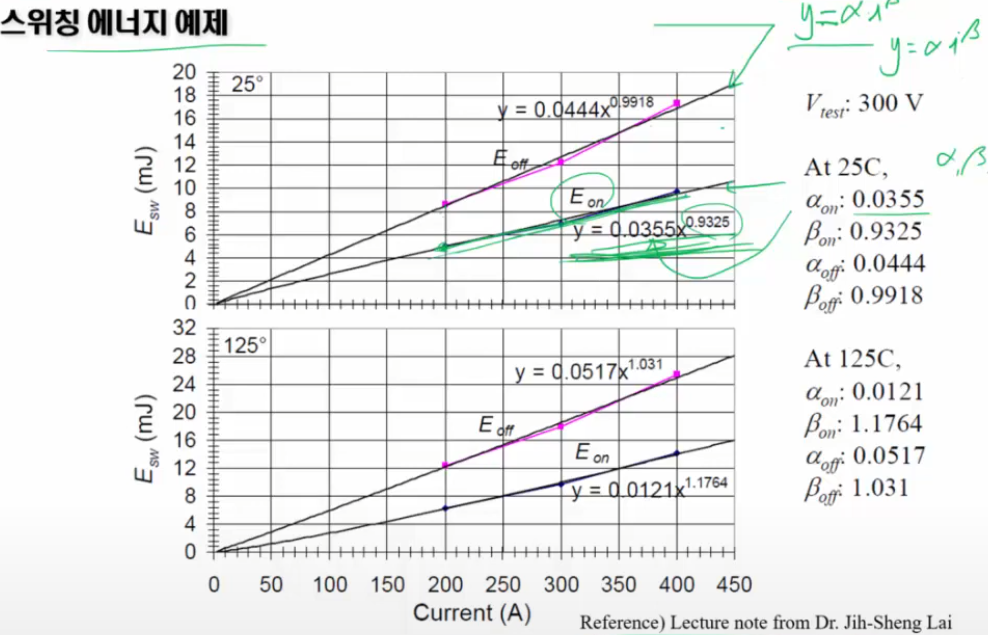


$$E_{sw}[T]=\alpha[T] I_{c}^{\beta[T]}

$$


$E_{sw}$ : 스위칭 에너지

$ I_{c} $   : 

$V_{CC}
$ : Test 전압(고정시켜놓고 테스트)

$V_{gs}
$ : 

$V_{G}
$ : 

$R_{G}
$ : 

$I_{d}
$ :

$I_{RRM}

$ : 역회복 전류 

$V_{d}
$ : 


$$$P_{s w}=\alpha I_m^\beta k_g f_{s w} \frac{1}{2 \sqrt{\pi}} \frac{V_{d c}}{V_{\text {test }}} \frac{\Gamma\left(\frac{\beta+1}{2}\right)}{\Gamma\left(\frac{\beta}{2}+1\right)}$$$



$$$P_{r r}=\frac{V_{D D} I_{R R M} t_B}{6} f_{s w}$$$


스위칭 한주기동안의 에너지 

Eon

Eoff

Err

평균소비전력= 스위칭한주기에너지 x 1/T (=fsw)

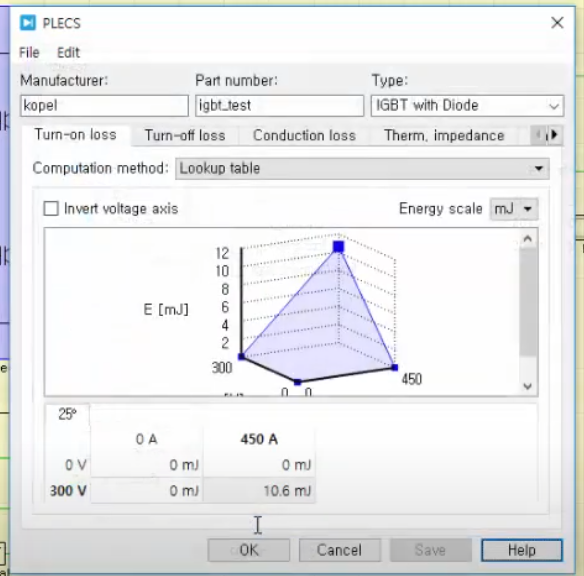

#### Swiching Loss

% 특성  - 소자 dataSheet from double pulse test
alpha_on     =0.0355          %         
beta_on      =0.9325;         %  
alpha_off    =0.0444;         %         
beta_off     =0.9918;         %
Vtest       =300;             % Double Pulse Test Voltage             


% 변경되야 되는거 운전시 값으로 변경해야되는거
Vdc         =280;             %             
Im          =315;             %  Irms*sqrt(2) = Irms 223  
kg_on       = 1 ;             %     
kg_off      = 1;              %     
fsw         =10000 ;          %스위칭 주파수        

Psw_on=alpha_on*(Im^beta_on)*kg_on*fsw*1/(2*sqrt(pi))*(Vdc/Vtest)*gamma((beta_on+1)/2)/gamma(beta_on/2+1)*0.001             %0.001 considering [MJ]
Psw_onFromEj=Eon*fsw*0.001 % Eon [mJ]
Psw_off=alpha_off*(Im^beta_off)*kg_off*fsw*1/(2*sqrt(pi))*(Vdc/Vtest)*gamma((beta_off+1)/2)/gamma(beta_off/2+1)*0.001
Psw_offFromEj=Eoff*fsw*0.001 % Eon [mJ]
SinglePsw = Psw_on+Psw_off

TotalPsw= 6*SinglePsw;
   
% P_rr=(/6)*fsw

#### Conducting Loss

Idon=Im;
Rds                                       % Drain-source on-resistance
SinglePConduc=Idon^2+Rds_on*DutyCycle;
PConduc      =SinglePConduc*6;

TotalDriveLoss=TotalPsw+PConduc;

예제 

3. KKU Model

## 2. Dynamic Power Converter Loss From Matlab

### 1.전체

[https://kr.mathworks.com/help/sps/high-power-converters.html?s_tid=CRUX_lftnav](https://kr.mathworks.com/help/sps/high-power-converters.html?s_tid=CRUX_lftnav)

### 3. Test Harness to Generate High-Power IGBT Device Characteristics

[https://kr.mathworks.com/help/sps/ug/test-harness-to-generate-high-power-igbt-device-characteristics.html](https://kr.mathworks.com/help/sps/ug/test-harness-to-generate-high-power-igbt-device-characteristics.html)

C:\Users\KDH2018-PC\Documents\MATLAB\Examples\R2023b\simscapeelectrical\TestHarnessIGBTExample\ConverterDesignIGBTWorkflow.mlx

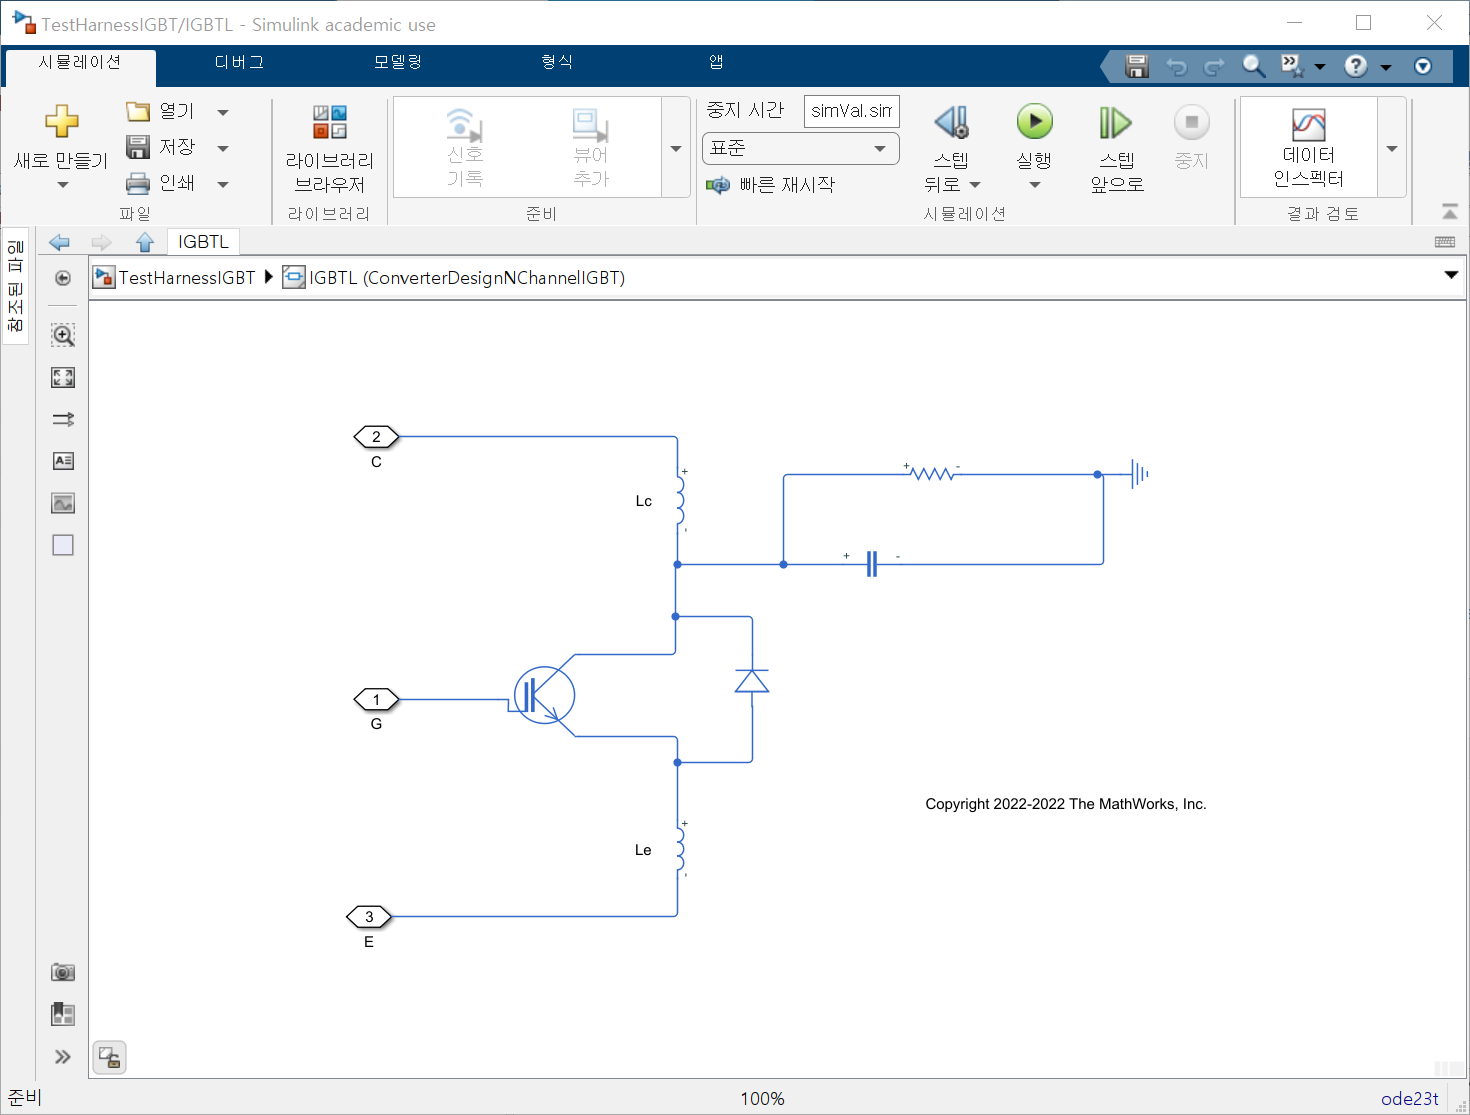

openExample('simscapeelectrical/TestHarnessIGBTExample')

#### N-Channel IGBT

[https://www.mathworks.com/help/releases/R2023b/sps/ref/nchanneligbt.html](https://www.mathworks.com/help/releases/R2023b/sps/ref/nchanneligbt.html)

#### Diode

[https://www.mathworks.com/help/releases/R2023b/sps/ref/diode.html](https://www.mathworks.com/help/releases/R2023b/sps/ref/diode.html)

ConverterDesignIGBTWorkflow

3.1 Application

HEVPMSMDriveTestHarnessPlotLossesTable

[https://www.mathworks.com/help/releases/R2023b/sps/ug/hev-pmsm-drive-test-harness.html](https://www.mathworks.com/help/releases/R2023b/sps/ug/hev-pmsm-drive-test-harness.html)

C:\Users\KDH2018-PC\Documents\MATLAB\Examples\R2023b\simscapeelectrical\HEVPMSMDriveTestHarnessExample\HEVPMSMDriveTestHarnessPlotLossesTable.m


4. 

MOSFET

[https://www.infineon.com/cms/en/product/power/mosfet/silicon-carbide/modules/?filterValues=~(551~(~%27Automotive))&visibleColumnIds=name,productStatusInfo,orderOnline,green,559_12_nom,496_nom,358,618,415,438,155_69_nom,155_70_nom,551](https://www.infineon.com/cms/en/product/power/mosfet/silicon-carbide/modules/?filterValues=~(551~(~%27Automotive))&visibleColumnIds=name,productStatusInfo,orderOnline,green,559_12_nom,496_nom,358,618,415,438,155_69_nom,155_70_nom,551)

[https://www.mathworks.com/help/releases/R2023b/sps/ref/nchannelmosfet.html](https://www.mathworks.com/help/releases/R2023b/sps/ref/nchannelmosfet.html)

[https://www.mathworks.com/help/releases/R2023b/sps/ug/sic-mosfet-tabulated.html](https://www.mathworks.com/help/releases/R2023b/sps/ug/sic-mosfet-tabulated.html)

Swiching Loss

Im=200
Eoff=4.27
Eon= 6.04
Psw_offFromEj=Eoff*fsw*0.001 % Eon [mJ]
Psw_onFromEj=Eon*fsw*0.001 % Eon [mJ]
SinglePsw = Psw_onFromEj+Psw_offFromEj
TotalPsw= 6*SinglePsw;


Conduction Loss

Idon=Im;
Rds_on = 5.50 %[mOhm]                                       % Drain-source on-resistance
SinglePConduc=Idon^2*Rds_on*DutyCycle;
SinglePConduc=Idon^2*Rds_on/2*0.001;
PConduc      =SinglePConduc*6;

TotalDriveLoss=TotalPsw+PConduc;


C:\Users\KDH2018-PC\Documents\MATLAB\Examples\R2023b\simscapeelectrical\SiCMOSFETFromSPICEResultsExample

